# ECSE 343:   Assignment 1

**Due Date: 1st February 2024    **

Name: Karen Chen Lai

Student Id.: 261107674

## Question 1: 16-bit floating point format. (5marks)

The half-precision (16-bit) floating point is one of the ways to store the numbers in computer memory. The half-precison has the following format,

- Sign Bit: 1 bit

- Exponent: 5 bits 

- Mantissa: 10 bits  

For all questions, show your work and justify your answers. 

a) How many positive numbers can be exactly represented in this floating point format as normalized floating point values. Express you answer as a formula in terms of the number of bits in the Matissa and in the Exponent, as well as a final value. Justify your answer.

*% There are two possibilities in the binary world, hence we have 2^M numbers for mantissa and 2^E - 2 numbers for the exponent.*

*Multiplying together we have (2^M) * (2^E -2) positive numbers (exclude 00000 and 11111)*

*Using the data that we have for half precision, we have (2^10) * (2^5 - 2) = 30720*

b) What is the largest positive number that can be represented using half-precision format?

*% The max E is 11110 (excluding inf) in binary which is equicalent to 30 in decimal.*

*e max = E max - bias = 30 - 15 = 15*

*max Mantissa is 1111111111*

*largest positive number = 1.1111111111 * 2^15*

*= 11111111111 * (2^ -10) * (2^15)*

*= (2^11 - 1) * (2^5) *

*=  65504*

c) What is the smallest positive normalized number that can be written in half-precision format?

*% For the smallest positive number with have min E = 00001 which is 1 in decimal*

*e min = E min - bias = 1 - 15 = -14*

*min Mantissa is 0000000000*

*smallest positive normalized number = 1.0000000000 * 2^(-14)*

*= 2^(-14)*

d) What is the smallest positive sub-normal (denormalized) number which can be represented in  half-precision format?

*% The samllest positive sub-normal has E = 00000*

*e = E - bias = 0 - 15 = -15*

*min M = 0000000001*

*The samllest positive sub-normal = 0.0000000001 * (2^(-15))*

*= 2^(-10) * 2^(-15)*

*=2^(-25)*

## Question 2 (5marks)

By default MATLAB uses double precision format (i.e. 64-bit floating point fomat) to store the numbers. However,  we can store a number in computer memory in different floating-point format. For example, we can store a number in half precision (16-bit) format as shown in the cell below.


x = half(0); % here we have instantiated x in the half-precion format.
whos x

  Name      Size            Bytes  Class    Attributes

  x         1x1                 2  half               





% % Any computations thus made using the variable x will be stored in half-precision format.
% NOTE: You might need to download a toolbox named Fixed Point Designer which is freely available toolbox in MATLAB.

% For any additional information.

(a) Write a MATLAB program that sums up $\frac{1}{n}$ for $n = 1, 2, . . . , 10000$ in double format (the default format in MATLAB).

n = 10000;
result = 0;
for i = 1:n % iterate from 1 to 10000
    result = result + (1/(i));
end
disp(result);

    9.7876



(b) Write a MATLAB program that sums  $\frac{1}{n}$ for $n = 1, 2, . . . , 10000$ in half precsion format.

x1 = half(0);  % Here I have already initialized the variable x1 in half-precision format.

n = 10000;
for i = 1:n % iterate from 1 to 10000
    x1 = x1 + half(1/(double(i)));
end
disp(x1);

    7.0859



(c) Write a MATLAB program that sums  sums up the same airthmatic sequence in in reverse order, i.e., for $n=10000,...,2,1$ 

x2 = half(0);  % Here I have already initialized the variable x2 in half-precision format.

n = 10000;
for i = n:-1:1 % iterate from 10000 to 1
    x2 = x2 + half(1/(double(i)));
end
disp(x2);

    9.7969




% Write your code here.

Compare the results obtatined in parts (b) and (c) with the results obtained in part (a) and explain your observations.

*% I am getting different exact results for part a, b and c but results of part a and c are close to each other. It is noticeable that the answer in part a is more accurate compared to others because double precision has much more decimals to store than half precision as same for the accuracy. For the answers of part b and c, the floating point error for part b is higher than part c since it starts summing up the small numbers towards big numbers, so the big terms are added first and their accuracy is being decreased after the addition of small terms due to the limited number of decimals that they can store, conversely for part c. So the result of part c is closer to part a.*

## Question 3 (5marks)

In this question you are tasked with computing the sum of the elements in a vector. 

a) Run the following code cell to compute the sum of the elements in a vector. Explain the discrepancy between the results obtained with MATLAB's in built function and the analytical solution. 

% There exists a discrepancy between the results obtained with built function and analytical function since the D_sum uses the single precision in which has lower degree of accuracy compared to the S1 which uses double precision due to the limited number of decimals that they can store. Therefore, the continuous addition of vector leads the D_sum to be little and little far away, increasing error,  from the S1 which is the exact sum with double precision.

N = 30000000;
rng(200);                 % select random seed for reproducible results
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S1 = sum(X); % use in built MATLAB function to compute the sum
toc

Elapsed time is 0.027854 seconds.




Error1 = abs(D_sum-S1)/D_sum  % compare the results

Error1 = single
5.1897e-08

b) Write a function S = naiveSum(X) that incrementally computes the sum of the values $x_1$, $x_2$, ..., $x_n$ incrementally:


$$S_1 = x_1 $$



$$S_2 = S_1 + x_2$$



$$\vdots$$



$$S_n = S_{n-1} + x_n$$


This can be implmented using a for-loop in matlab.

Test your function using the following code:

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S2 = naiveSum(X); % use your function to compute the sum
toc

Elapsed time is 0.082094 seconds.



Error2 = abs(D_sum-S2)/D_sum  % compare the results

Error2 = single
3.0919e-05

c) Write a function S =  *rSum(X) *that uses recursion to compute the sum of the elements provided in the vector X.  This approach is summarized as follows,


$$S(X) = 
     \begin{cases}
       0 &\quad  \text{if   } n=0 \\
       x_1 &\quad \text{if   } n=1  \\
     S(X(1:n/2))+S(X(n/2 +1 : n) &\quad\text{if   } n>1 \\ 
     \end{cases}$$


Note that $n$ is the number of elements in X. Also be careful to address the case where $\frac{n}{2}$ is not an integer. Use the following code to test your function.

N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S3 = rSum(X); % use your function to compute the sum
toc

Elapsed time is 23.972537 seconds.



Error3 = abs(D_sum-S3)/D_sum  % compare the results

Error3 = single
5.1897e-08

d) The recursive function calls add a significant amount of cpu cost in the algorithm in part c. Propose, implement, and test a compromise algorithm using both the naive and recursive approach that has both good accuracy and good cpu cost. Compare your algorithm to the MATLAB function sum. Explain your design decision for the proposed algorithm. Test your algorithm in the following code cell:


N = 30000000;
rng(200);                 % select random seed for reproducible resutls
XL = normrnd(1,0.1,N,1);  % Generate normal random numbers
X  = single(XL);          % Convert to single precision float

D_sum = sum(XL);  % We use the double precision sum as the "exact" ground truth.

tic
S4 = improvedSum(X); % use your function to compute the sum
toc 

Elapsed time is 0.308564 seconds.



Error4 = abs(D_sum-S4)/D_sum  % compare the results

Error4 = single
5.1897e-08

*% The proposed algorithm is a use of combination of algorithms in part b and c, in which provides an elapsed time of around 0.3054 seconds and part b and c have an elapsed time of 0.1006 and 17.7653 seconds approximately, respectively. This algorithm basically decides whether to use recursive algorithm or naive algorithm depending on vector length, it will use the recursive algorithm for a vector length over 1000, it uses naive algorithm otherwise. The elapsed time is very small such that implies a low cpu cost and have a good accuracy at the same since the relative error is small.*

e) Explain the difference in accuracy and cpu cost for the above methods for computing the sum. 

*%  For the first one, the MATLAB built-in function tends to be the fastest one for doule precision but it could lead to rounding errors for single-precision floats for large vectors. For the second one, naive algorithm, has a greater error compared to the built-in function which means it has rounding errors as well, it alsodoes not have a high accuracy degree because its output is different from others due to rounding erorrs, on the other hand, its cpu cost is low since its elapsed time is relavetively small. For the thrid one, rSum, it has a good accuracy by addition of small portions of vectors, but because of that, it leads to big memory consumption with the recursion and a very slow speed with a big elapsed time for large vector, hence cpu cost is high. For the last one, improvedSum, it has a relatively balanced accuacy and cpu cost that are both good compared to the other three methods since it combines and utilizes the advantages of both naive and rSum algorithms.*

## Question 4: (5marks)

The derivative of a function, f(x), can be computed using the finite difference method, which can be derived using the first-order terms of the Taylor series expansion of the function, about : 

$f{\left(x_0 +h\right)}=f{\left(x_0 \right)}+hf^{\prime } {\left(x_0 \right)}+\frac{1}{2!}f^{\prime \prime } {\left(x_0 \right)}h^2 +\frac{1}{3!}f^{\prime \prime \prime } {\left(x_0 \right)}h^3 +\ldots$                    (4.1)

Rearranging terms to solve for $f^{\prime } {\left(x_0 \right)}$  and ignoring (truncating) the higher-order terms, we obtain the first order approximation of derivative

$f^{\prime } {\left(x_0 \right)}\;\approx \frac{f{\left(x_0 +h\right)}-f{\left(x_0 \right)}}{h}$                                                                          (4.2)

(a) What is the truncation error for the above approximation? How does the trunction error behave with decrease in the value of $h$ ?

*% If we truncate the higher-order terms, then the truncation error will be all the terms except the first term and the leading term of truncation error is *$\frac{h^2 }{2!}{f^{\prime } }^{\prime } \left(X\right)$. Obeserving the leading term, we know that if the value of h decreases, then truncation error will decrease as well due to the directly proportionality $h^2$. Hence the truncation error will decrease quadratically with the decrease of value of h.

(b) To compute the derivative of $f (x) = sin(x)$, we can use the equation (4.2) as,

                        $\frac{d sin(x)} {dx}  \approx$ $\frac{\sin {\left(x+h\right)}-\sin {\left(x\right)}}{h}$                                                                                                   (4.3)

 In the cell below, write a MATLAB program that can compute the derivative of the $sin(x)$ at $x=45$ for different values of $h$. Use $h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$.

We know the true value of derivative of $sin(x)$ at $x=45$ is $cos(45)$. Plot the absolute error vs $h$.  Make sure the axis are labeled and the plot has an appropriate title.

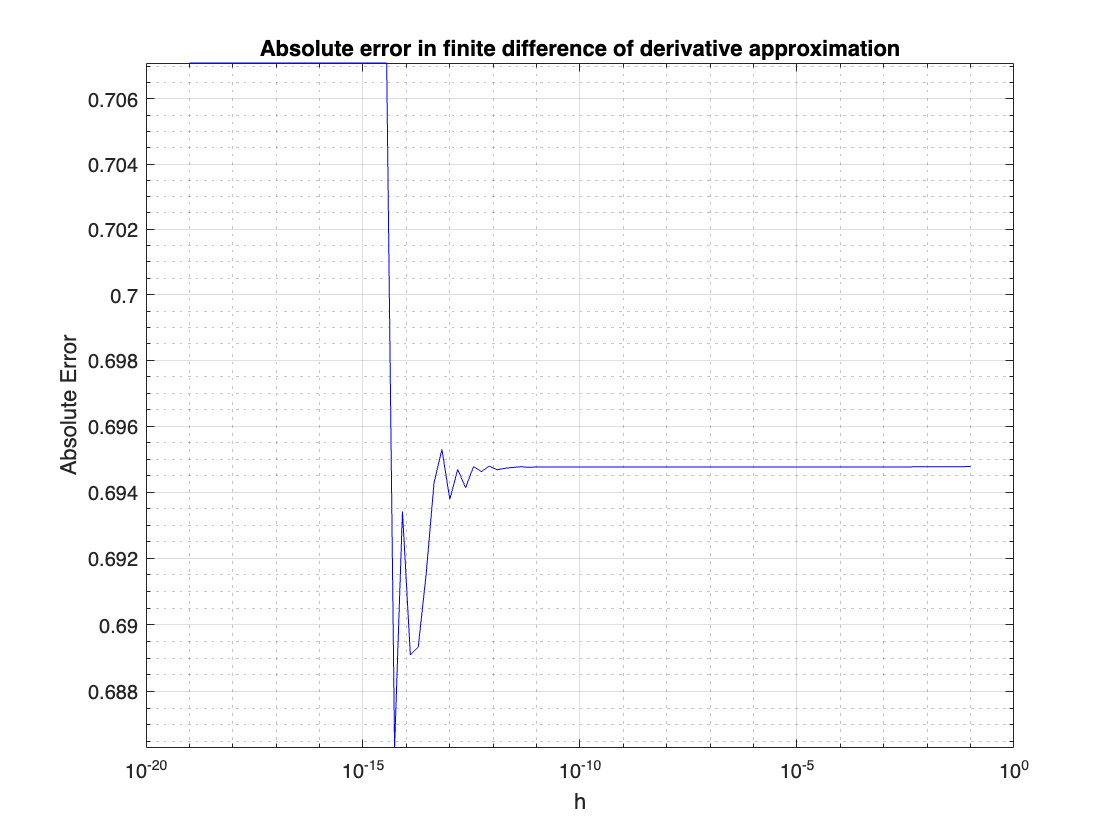

% write your code here.

h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1

f = @(x) sin(deg2rad(x));
df = @(x) cos(deg2rad(x));

x = 45;
true_derivative = df(x);
h_values = logspace(-19, -1, 100);% Generate h values

approx_derivatives = (f(x + h_values) - f(x)) ./ h_values;% approximate derivatives
absolute_errors = abs(approx_derivatives - true_derivative);% absolute errors

loglog(h_values, absolute_errors, 'b-');% Plot absolute error vs h
xlabel('h');
ylabel('Absolute Error');
title('Absolute error in finite difference of derivative approximation');
grid on;

(c) The function $sin(x+h)-sin(x)$ can be transformed into another form  using the trigonometric formula

$sin(\phi) - sin(\psi) = 2 cos(\frac{\phi+\psi}{2}) sin((\frac{\phi-\psi}{2})$                                                                                                    (4.4)

Using the above formula, transform the equation (4.3) to compute the derivative of $sin(x)$ and write a MATLAB program that computes the derivative of the $sin(x)$ at $x=45$ for $h=10^{-19},10^{-18}, 10^{-17} ,..., 10^{-2}, 10^{-1}, 1$.

Compare the derivative obtained with the true value and plot the absolute error vs $h$.  Make sure the axes are labeled and the plot has an appropriate title.

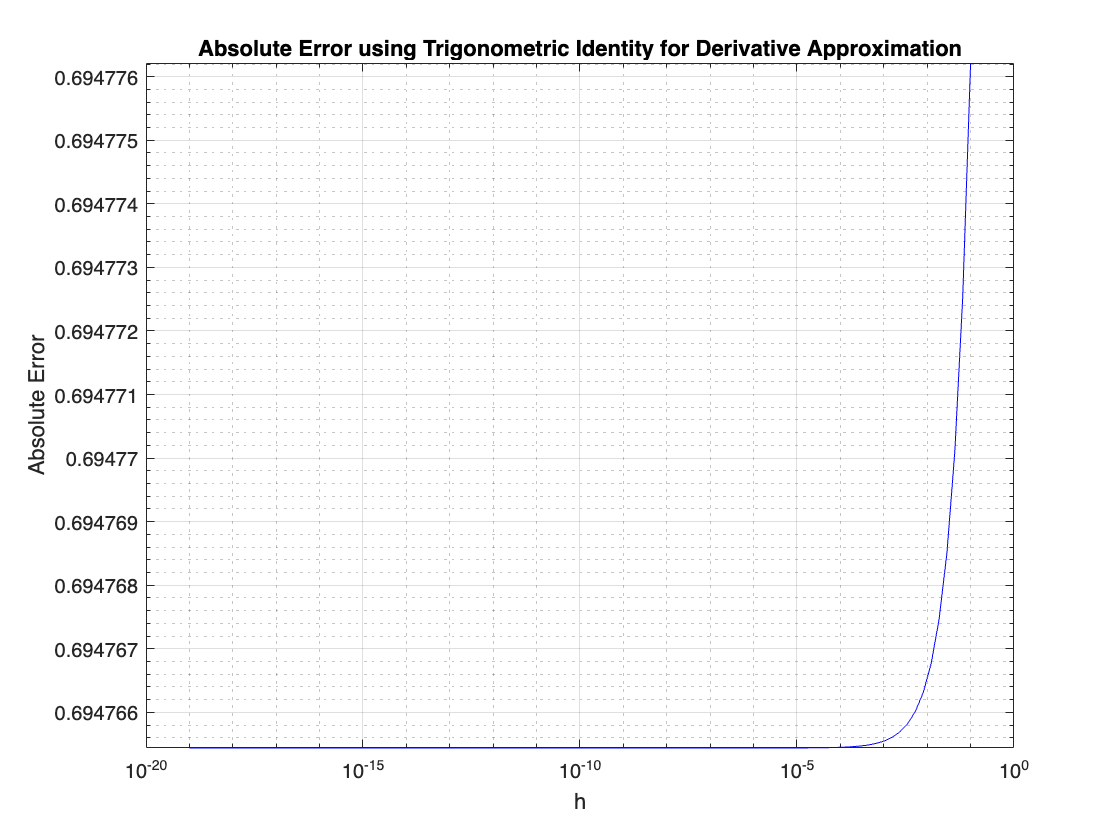

% write your code here.

h = logspace(-19,0,100);  % h is a vector here that contains 100 values between 10^(-19) to 1

f = @(x) sin(deg2rad(x));
df = @(x) cos(deg2rad(x));
x = 45;
true_derivative = df(x);
h_values = logspace(-19, -1, 100);
approx_derivatives = zeros(size(h_values));% Initialize vector

for i = 1:length(h_values)% Compute using the trigonometric identity
    h = h_values(i);
    approx_derivatives(i) = 2*cos(deg2rad(x + h/2))*sin(deg2rad(h/2))/h;
end

absolute_errors = abs(approx_derivatives - true_derivative);% absolute errors

loglog(h_values, absolute_errors, 'b-');% Plot
xlabel('h');
ylabel('Absolute Error');
title('Absolute Error using Trigonometric Identity for Derivative Approximation');
grid on;

(d) Explain the difference in accuracy between the results obtained in part (b) and (c). 

*% For part b if we are using two similar numbers, nearly equal, to perform subtractive cancellation between them then it would produces a result without high degree of accuracy, since a large relative error can be produced by loss of precision through operation of digits. The plot for finite difference method demonstrates that there is a point where the error increases due to the subtractive cancellation and rounding errors. On the other hand, part c uses a direct subtraction of two similar numbers, by observing its formula, it is noticeable that the product of cosine and sine will not be affected by subtractive cancellation, particularly for samll h, which can produce a more accurate result for small values of h. The plot for trigonometry identity method also shows that when h gets smaller the error has a consistent  and stable decrease and there is not any increase. Thus, the trigonometric identity method is much more accurate than the finite difference method since it performs better on reducing numerical errors inherent in the operations.*

## Question 5: Solving linear systems of equations. (10 marks)

    a) Write the  functions named *forward_sub *to perform the forward substitution on a lower triangular matrix. Add your function in the appendix of this file.

You can check your function by comparing the obtained results with the MATLAB's built in backslash operator. 

 Use the cell below to test the correctness of your function on the provided lower triangular matrix.  

 A = tril(magic(4)) % A is a 4x4 lower triangular matrix   

A =     16     0     0     0
     5    11     0     0
     9     7     6     0
     4    14    15     1


 b = [1; 2; 3; 4];     % right hand side vector of size 4x1

%---------------------------------------------------------------------------------------------------------
 % call your forward_sub function and solve  Ax = b    % (where A is a
 % lower triangular square matrix)
num = forward_sub(A,b);
matlab_result = A \ b;
disp("FORWARD SUBSTITUTION");

FORWARD SUBSTITUTION


disp("Result of my function is:");

Result of my function is:


disp(num);

    0.0625
    0.1534
    0.2273
   -1.8068



disp("Result of MATLAB:");

Result of MATLAB:


disp(matlab_result);

    0.0625
    0.1534
    0.2273
   -1.8068



 b) Write the *backward_sub *function to perform the backward substitution on a lower triangular matrix. Add your function in the appendix of this file.

 Use the cell below to test the correctness of your function by comparing your solution with the MATLAB's built in backslash operator.

  A = triu(magic(4)) % A is a 4x4 upper triangular matrix   

A =     16     2     3    13
     0    11    10     8
     0     0     6    12
     0     0     0     1


 b = [1; 2; 3; 4];     % right hand side vector of size 4x1

%---------------------------------------------------------------------------------------------------------
 % call your backward_sub function and solve  Ax = b    % (where A is a
 % upper triangular square matrix)
num = backward_sub(A,b);
matlab_result = A \ b;
disp("BACKWARD SUBSTITUTION");

BACKWARD SUBSTITUTION


disp("Result of my function is:");

Result of my function is:


disp(x);

    45



disp("Result of MATLABs:");

Result of MATLABs:


disp(matlab_result);

   -2.2926
    4.0909
   -7.5000
    4.0000



    c) Write a function named *LU_decomposition.m * in the Appendix of this file to compute the LU factorization using Gaussian Elimination. 

    d)  In the cell below use the LU decomposition implemented in part (c) along with forward and backward substitution functions written in part (a)  and (b), respectively, to solve the following system of equations. List the values of vector X obtained.  


$$\underset{A}{\underbrace{{\left[\begin{array}{cccc}
1e-16 & 50 & 5 & 9\\
0.2 & 5 & 7.4 & 5\\
0.5 & 4 & 8.5 & 32\\
0.89 & 8 & 11 & 92
\end{array}\right]}} } \underset{X}{\underbrace{{\left[\begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right]}} } =\ \underset{b}{\underbrace{{\left[\begin{array}{c}
40\\
52\\
18\\
95
\end{array}\right]}} }$$


A = [1e-16 50 5 9; 0.2 5 7.4 5; 0.5 4 8.5 32; 0.89 8 11 92];
b = [40; 52; 18; 95];
[L, U] = LU_decomposition(A);
y = forward_sub(L,b);
x = backward_sub(U, y);
disp("LU decomposition:");

LU decomposition:


disp(x);

 -426.3256
   -1.0469
   13.1250
    2.9688



    e) Write a function named *LU_rowpivot.m *to compute the Gaussian Elimination based LU factorization **using the partial pivoting** (row pivoting). Choose the elements with maximum magnitude as pivots. The function should take matrix  as the input and should output L, U and P matrices. Write your function in the Appendix of this file.

 f) In the cell below use the LU decomposition with partial pivoting implemented in part (b) along with forward and backward substitution functions written in part (c) to solve the above system of equations. List the values of vector X obtained.  

A = [1e-16 50 5 9; 0.2 5 7.4 5; 0.5 4 8.5 32; 0.89 8 11 92];
b = [40; 52; 18; 95];
[L, U, P] = LU_rowpivot(A);
y = forward_sub(L, P*b);
x = backward_sub(U, y);
disp("LU Decomposition with Partial Pivoting")

LU Decomposition with Partial Pivoting


disp("solution:");

solution:


disp(x);

 -595.4623
   -2.1518
   21.6035
    4.3971



   g) Comment on solutions obtained in part (d) and (f). Use the residual to determine which solution is more accurarte.

    *% Through the residual of the solution vector r = b - Ax we can analyze and determine the difference between b, the right-hand side vector, and the product of the matrix A and solution vector x. I calculated the residuals separately for part d and part f in which shows that the residuals for part f is much more smaller and closer to 0, implying that result in part f is much more accurate compared to part d since smaller residual norm hints at a better fit to the data. *

## Appendix

###  Write functions for Question 3 are here.

function S = naiveSum(X)
% returns the sum of all elements in vector X
    S = 0;
    for i = 1: length(X)
        S = S + X(i);
    end
end

%--------------------------------------------------------------------------

function S = rSum(X)
% Returns the sum of all elements in vector X using the recurssion
    n = length(X);
    if n == 0
        S = 0;
    elseif n == 1
        S = X(1);
    else
        mid = floor(n/2);
        S = rSum(X(1:mid)) + rSum(X(mid+1 : n));
    end
end

%--------------------------------------------------------------------------
function S = improvedSum(X)
% Returns the sum of all elements in vector X
    n = length(X);
    limit = 1000;
    if n <= limit
        S = naiveSum(X);
    else
        mid = floor(n/2);
        S = improvedSum(X(1:mid)) + improvedSum(X(mid+1 : n));
    end
end


### Write code for Question 5 here

function [L, U] = LU_decomposition(A)
% L  is lower triagular matrix
% U is upper triangular matrix 
    n = size(A,1);
    L = eye(n);
    U = A;
    for k = 1:n-1
        for i = k+1:n
            factor = U(i,k) / U(k,k);
            L(i,k) = factor;
            U(i, k:end) = U(i, k:end) - factor * U(k, k:end);
        end
    end
end


function [L, U, P] = LU_rowpivot(A)
% L  is lower triagular matrix
% U is upper triangular matrix 
% P is the permutation matrix
% P*A = L*U
    n = size(A,1);
    L = eye(n);
    U = A;
    P = eye(n);
    for k = 1:n-1
        [~, pivot_row] = max(abs(U(k:end,k)));
        pivot_row = pivot_row + k-1;

        temporary = U(k,:);
        U(k,:) = U(pivot_row, :);
        U(pivot_row, :) = temporary;

        temporary = L(k,1:k-1);
        L(k,1:k-1) = L(pivot_row, 1:k-1);
        L(pivot_row, 1:k-1) = temporary;

        temporary = P(k, :);
        P(k, :) = P(pivot_row, :);
        P(pivot_row, :) = temporary;

        for i = k+1:n
            factor = U(i,k) / U(k,k);
            L(i,k) = factor;
            U(i,k:end) = U(i,k:end) - factor * U(k,k:end);
        end
    end
end

function y = forward_sub(L,b)
% y is the vector
% L is the lower triangular matrix
    n = length(b);
    y = zeros(n,1);
    for i = 1:n
        y(i) = ( b(i) - L(i, 1: i-1) * y(1:i-1) ) / L(i,i);
    end
end 

function X = backward_sub(U,y)
% X is the vector
% U is the upper triangular matrix
    n = length(y);
    X = zeros(n,1);
    for i = n:-1:1
        X(i) = ( y(i) - U(i, i+1:end) * X(i+1:end) ) / U(i,i);
    end
end 